*셀배열 예제 

예)'char' 와  "string"

['Park'; 'Lee']   % 에러남 (길이 다름)

%['Park'; 'Lee'] 

string type 으로 행렬 만들면 실행가능

["Park"; "Lee"]

ans = 2×1 string array
    "Park"
    "Lee"


1. 셀 배열 생성 (서로 다른 타입 저장 가능),

C = { 'Kim', 20, [90 85 88]; 
      'Lee', 22, [75 80 82]};

2. 전체 출력

disp('셀 배열 C = ')

셀 배열 C = 


disp(C)

    {'Kim'}    {[20]}    {[90 85 88]}
    {'Lee'}    {[22]}    {[75 80 82]}



3. 내용 접근 (중괄호 사용)

disp('이름:')

이름:


disp(C{1,1})   % 'Kim'

Kim



disp('나이:')

나이:


disp(C{2,2})   % 22

    22




disp('점수 배열:')

점수 배열:


disp(C{1,3})   % [90 85 88]

    90    85    88



4. 셀 자체접근 (소괄호 사용)

disp('셀 형태 그대로:')

셀 형태 그대로:


disp(C(1,1))   % {'Kim'}

    {'Kim'}



5. 빈 셀 만들어서 채우기

C1 = cell(2,2);

C1{1,1} = 'Park';
C1{1,2} = 25;
C1{2,1} = [1 2 3];
C1{2,2} = rand(2);
celldisp(C1)

 
C1{1,1} =
 
Park
 
 
C1{2,1} =
 
     1     2     3

 
 
C1{1,2} =
 
    25

 
 
C1{2,2} =
 
    0.1966    0.6160
    0.2511    0.4733

 


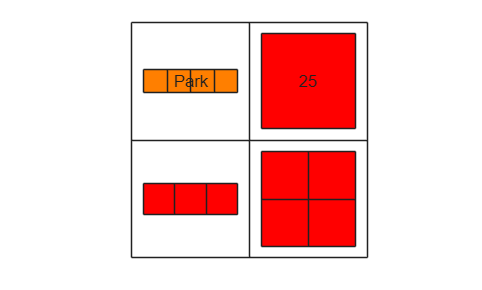

cellplot(C1)

6. 셀 안의 내용 모두 한번에 보고 싶을 때 -> 표로 변환해야 함

T = cell2table(C);
disp(T)

      C1       C2          C3      
    _______    __    ______________

    {'Kim'}    20    90    85    88
    {'Lee'}    22    75    80    82



7. 각 학생의 성적의 평균을 구해서 80이상인 경우의 이름과 나이 출력

avg1 = mean(C{1,3})

avg1 = 87.6667

avg2 = mean(C{2,3})

avg2 = 79


if avg1 >= 85
C{1,1}
C{1,2}
end

ans = 'Kim'

ans = 20


if avg2 >= 80
C{2,1}
C{2,2}
end